# Trabajo Práctico 1: Ejercicio 2

clear;
R = 2.54; %ohm
L = 0.85 * 10^-3; %H
Kt = 74.1 * 10^-3; %N*m/A
Kb = 0.074; %V/(rad/s)
J = 8.42 * 10^-6; %N*m/(rad/s^2)
b = 25.4 * 10^-6; %N*m/(rad/s)
Ve = 70; %V
Vsw = 12; %V
Ka = Ve/Vsw;
Ks = 4/7150; % V/rpm -> 7150rpm = 748.746rad/s
Gs = 1;

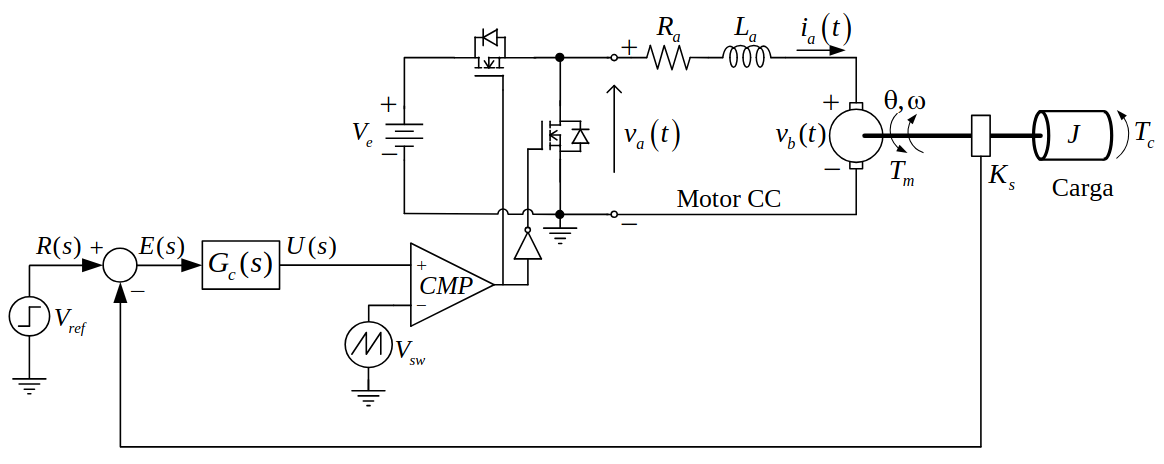

## Punto A

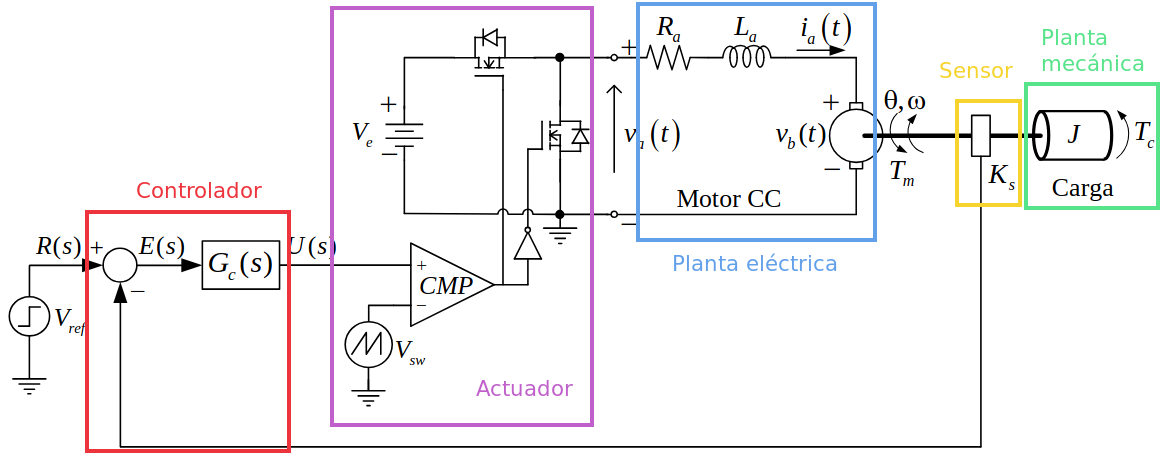

## Punto B

Torque eletromagnético:

$T_e(t) = K_t i_a(t)$ | $K_t$: Cte. prop. par motor y corriente de armadura | $i_a$: Corriente de armadura


$$T_e(s) = K_t I_a(s)$$



$$\frac{T_e(s)}{I_a(s)}=K_t$$


2da Ley de Newton en Motor:

$T_e(t) - b \cdot \omega(t) = J \frac{d\omega(t)}{dt}$ | $b$: Coef. Fricción | J: Momento de Inercia


$$T_e(s)-v\Omega(s)=Js\Omega(s)$$



$$T_e(s) = \Omega(s) (Js+b)$$



$$\frac{\Omega(s)}{T_e(s)}=\frac{1}{Js+b}$$


Tensión contra-electromotriz:

$v_b(t) = K_b \omega(t)$ | $K_b$: Cte. Prop. velocidad angular y tensión inducida

KVL en circuito de armadura:


$$v_a(t) = R\cdot i_a(t) + L \frac{di(t)}{dt} + v_b(t)$$



$$v_a(t) = R\cdot i_a(t) + L \frac{di(t)}{dt} + K_b\omega(t)$$



$$V_a(s) = R I_a(s) + L s I_a(s) + K_b \Omega(s)$$



$$V_a(s) - K_b\Omega(s)=I_a(s)(Ls+R)$$



$$I_a(s) = \frac{V_a(s) - K_b\Omega(s)}{Ls + R}$$


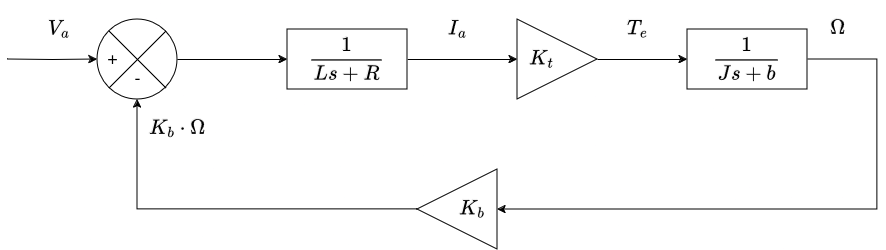

plantaLA = tf(1,[L R]) * Kt * tf(1, [J b])

plantaLA =
 
                  0.0741
  ---------------------------------------
  7.157e-09 s^2 + 2.141e-05 s + 6.452e-05
 
Continuous-time transfer function.
Model Properties


plantaLC = feedback(plantaLA,Kb,-1);
zpk(plantaLC)

ans =
 
      1.0354e+07
  ------------------
  (s+2705) (s+286.6)
 
Continuous-time zero/pole/gain model.
Model Properties


## Punto C

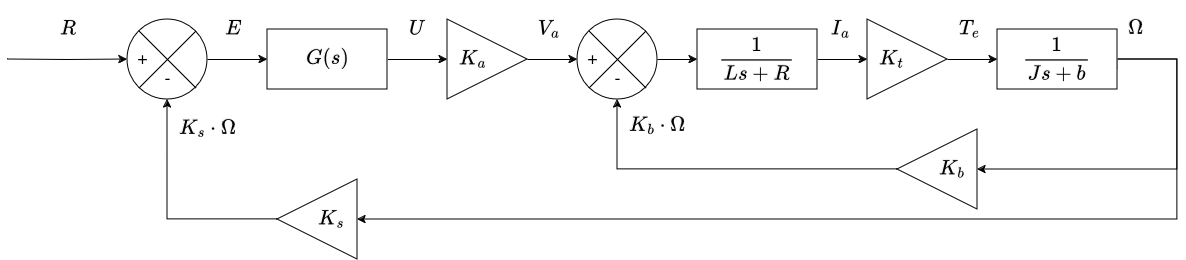

### Lazo Abierto

#### Función de Transferencia

GLA = Gs * Ka * plantaLC

GLA =
 
                  0.4322
  --------------------------------------
  7.157e-09 s^2 + 2.141e-05 s + 0.005548
 
Continuous-time transfer function.
Model Properties


#### Ganancia

[cerosLA, gananciaLA] = zero(GLA);
gananciaLA

gananciaLA = 6.0395e+07

#### Ceros

cerosLA % no tiene


cerosLA =

  0×1 empty double column vector



#### Polos

polosLA = pole(GLA)

polosLA = 1.0e+03 *

   -2.7046
   -0.2866


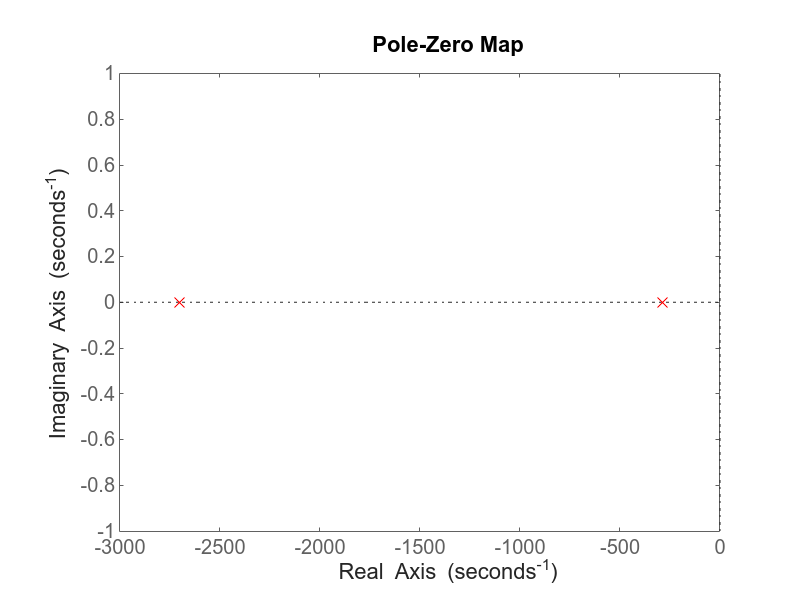

pzplot(GLA, 'r')

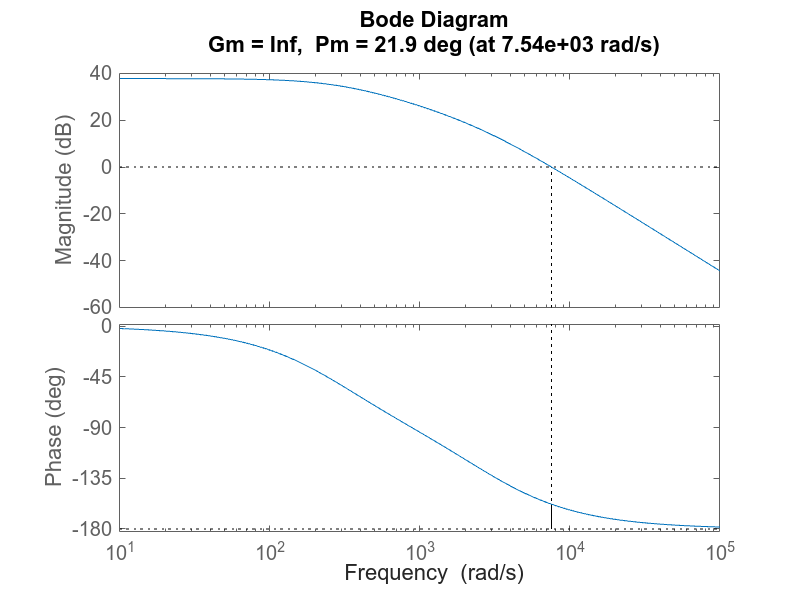

margin(GLA)

### Lazo Cerrado

#### Función de transferencia

GLC = feedback(GLA, Ks, -1)

GLC =
 
                 0.4322
  -------------------------------------
  7.157e-09 s^2 + 2.141e-05 s + 0.00579
 
Continuous-time transfer function.
Model Properties


#### Ganancia

[cerosLC, gananciaLC] = zero(GLC);
gananciaLC

gananciaLC = 6.0395e+07

#### Ceros

cerosLC % no tiene


cerosLC =

  0×1 empty double column vector



#### Polos

polosLC = pole(GLC)

polosLC = 1.0e+03 *

   -2.6906
   -0.3007


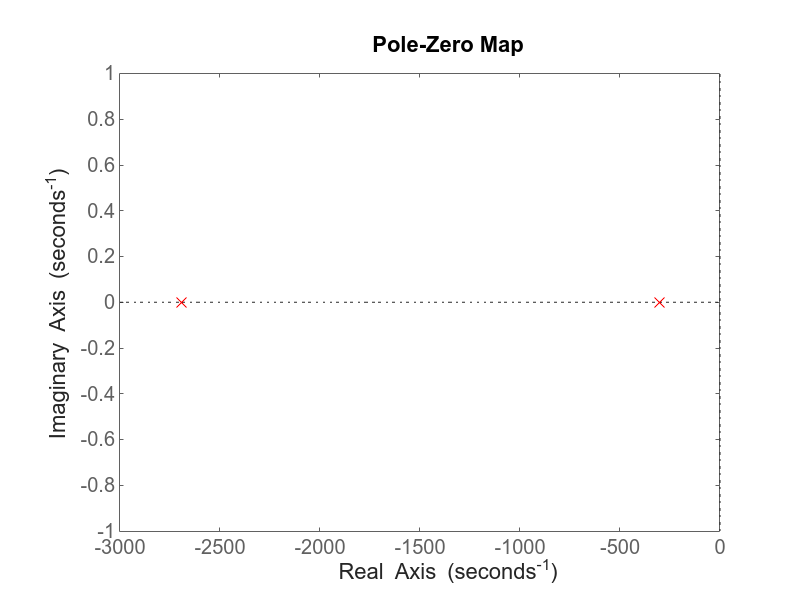

pzplot(GLC, 'r')

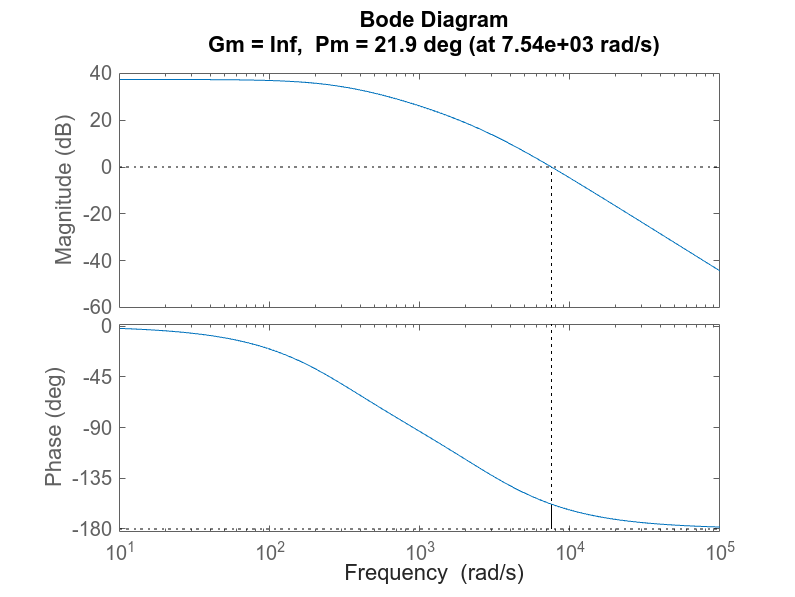

margin(GLC)

### Respuesta al escalón unitario

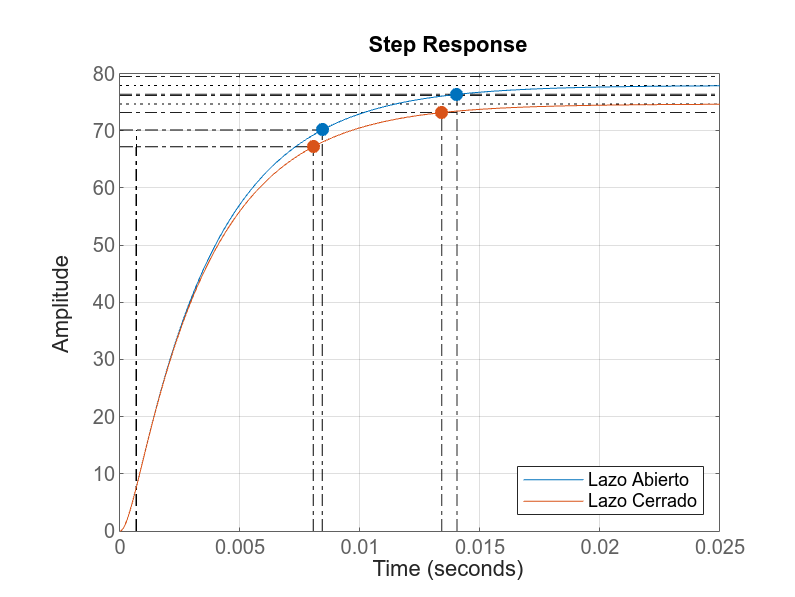

h = stepplot(GLA, GLC);
h.showCharacteristic('RiseTime')
h.showCharacteristic('SettlingTime')
grid on
legend("Lazo Abierto", "Lazo Cerrado", "Location", "southeast")

stepinfo(GLA)

ans = struct with fields:
         RiseTime: 0.0077
    TransientTime: 0.0140
     SettlingTime: 0.0140
      SettlingMin: 70.1668
      SettlingMax: 77.8687
        Overshoot: 0
       Undershoot: 0
             Peak: 77.8687
         PeakTime: 0.0265


stepinfo(GLC)

ans = struct with fields:
         RiseTime: 0.0074
    TransientTime: 0.0134
     SettlingTime: 0.0134
      SettlingMin: 67.2508
      SettlingMax: 74.6397
        Overshoot: 0
       Undershoot: 0
             Peak: 74.6397
         PeakTime: 0.0280


## Punto D

Tp = 95 * 10^-3; %Nm
%open_system("tp1ej2pD")

## Punto E

Vref = 4; %V
%open_system("tp1ej2pE")